Q1:  Also explore the “Uniform filter”. What is the difference with the “Gaussian filter”? What parameters would you choose to make the result of the uniform filter similar to the result from the Gaussian filter? Why can’t you make the results exactly the same?

- Uniform has every allowable value equally similarly while Gaussian has single most likely value. The Gaussian has more white density toward the center of the pixel while Uniform has more constant density piece by piece. 

- To make the image similar to the Gaussian, I set the following parameters for Uniform filter: Filter size: 7, filter shape: elliptic 

- The result cannot be exactly the same since the way the whiteness of each pixel in each filter is formed differently. 

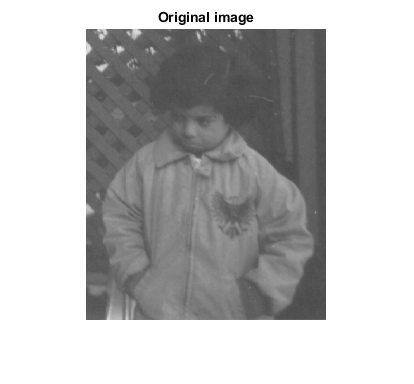

%run('C:\Program Files\DIPimage 2.9\dipstart.m');
Image1 = imread('pout.tif');
imshow(Image1)
title('Original image')

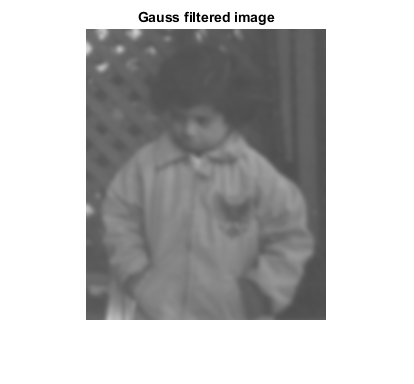

Image1gauss = imgaussfilt(Image1,2);
imshow(Image1gauss)
title('Gauss filtered image')

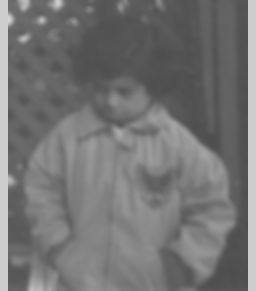

Displayed in figure 2


unif(Image1,7,'elliptic')

Q2: Try out the above example and understand it, then design your owner kernel or mask and apply it to your image. And please add explanation for your filter design and final filtered image. 

- First, I create my matrix which is a convolution of a random 3-by-3 matrix and a random 1-by-1 matrix using “conv2”: 

Mymatrix = conv2(rand(1), rand(2))

- Then I used imfilter with the parameter are the original image and the matrix I made above: 

Imfilter(Image1, mymatrix)

I = imread('coins.png');
h = ones(5,5) / 25;
I2 = imfilter(I,h);
imshow(I), title('Original Image');
figure, imshow(I2), title('Filtered Image')

mymatrix = conv2(rand(3), rand(1));
Image2 = imfilter(Image1, mymatrix);
imshow(Image1), title('original')
imshow(Image2), title('my filer applied')

Q3: Read this paper http://dmuw.zum.de/images/6/6d/Matrix-en.pdf and understand it. Then implement at least 2 types of operations in matlab(you can choose your own images): 

Operation: explore RGB

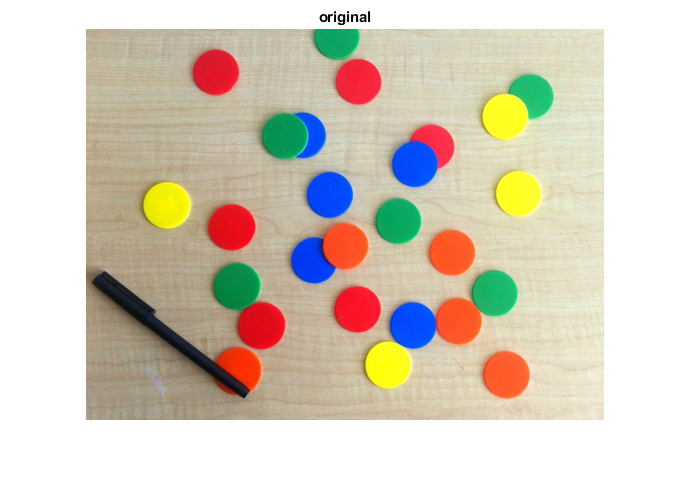

Image3 = imread('coloredChips.png');
imshow(Image3), title('original')

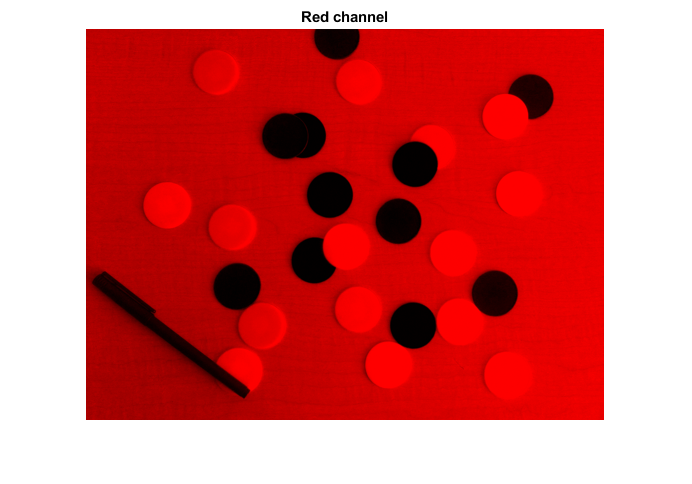

Red = Image3(:,:,1);
Green = Image3(:,:,2);
Blue = Image3(:,:,3);
a = zeros(size(Image3, 1), size(Image3, 2));
imshow(cat(3,Red,a,a)), title('Red channel')

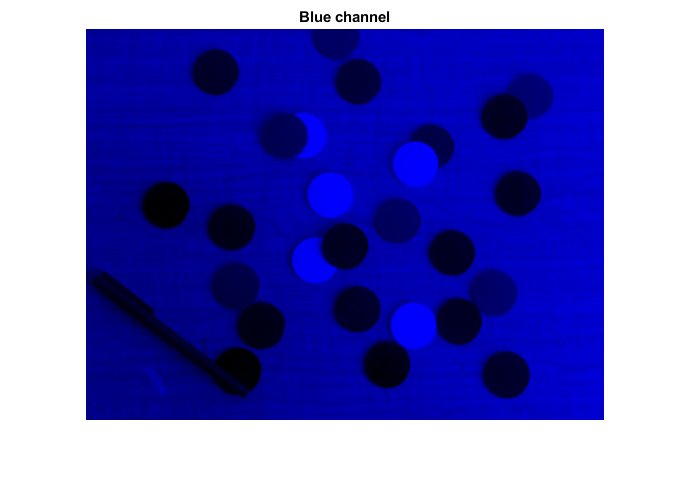

imshow(cat(3,a ,a, Blue)), title('Blue channel')

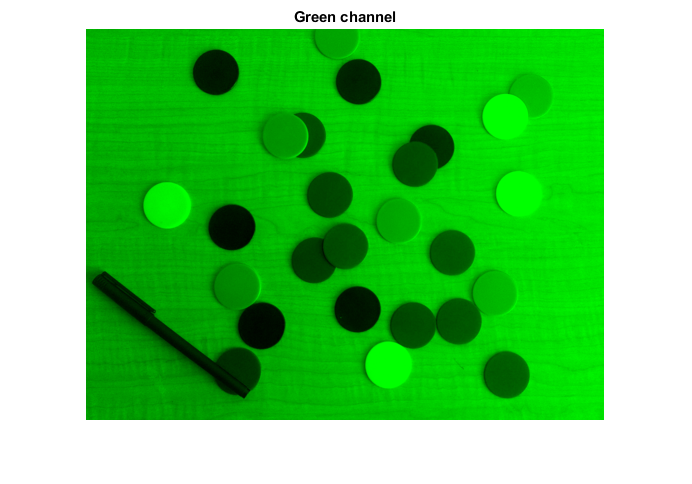

imshow(cat(3,a,Green,a)), title('Green channel')

Operation: Matrix transformation

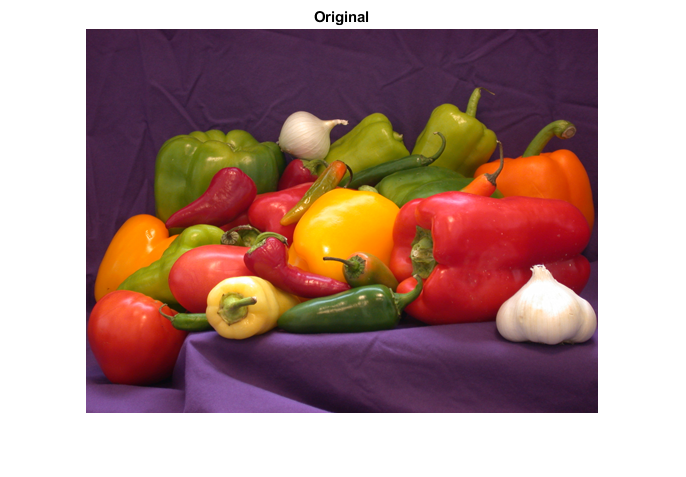

Image1 = imread('peppers.png');
[nrows, ncols, nslices] = size(Image1);
midx=ceil((ncols+1)/2);
midy=ceil((nrows+1)/2);
Mr = [cos(pi/4) sin(pi/4); -sin(pi/4) cos(pi/4)]; %45 degree rotation
% rotate about center
[X, Y] = meshgrid(1:ncols,1:nrows);
XYt = [X(:)-midx Y(:)-midy]*Mr;
XYt = bsxfun(@plus,XYt,[midx midy]);

xout = round(XYt(:,1)); yout = round(XYt(:,2)); % nearest neighbor!
outbound = yout<1 | yout>nrows | xout<1 | xout>ncols;
zout=repmat(cat(3,1,2,3),nrows,ncols,1); zout=zout(:);
xout(xout<1) = 1; xout(xout>ncols) = ncols;
yout(yout<1) = 1; yout(yout>nrows) = nrows;
xout = repmat(xout,[3 1]); yout = repmat(yout,[3 1]);
imagerot = Image1(sub2ind(size(Image1),yout,xout,zout(:))); % lookup
imagerot = reshape(imagerot,size(Image1));
imshow(Image1), title('Original')

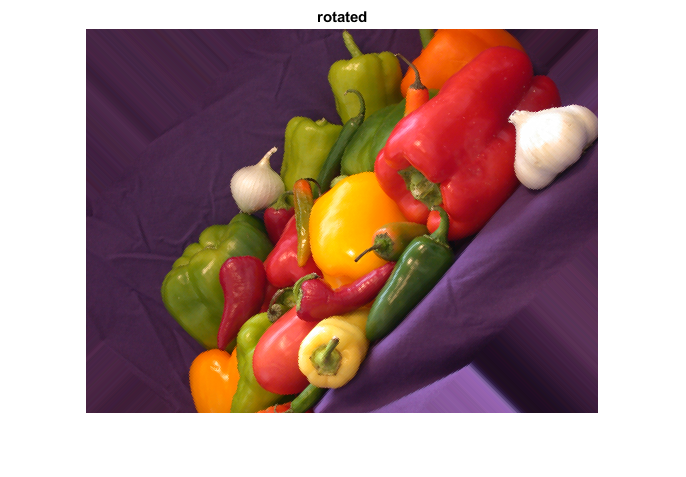

imshow(imagerot), title('rotated')